# Calcolo Numerico con Laboratorio 

# Compito a casa 

# 11 ottobre 2021

Questa esercitazione è stata svolta da Francesco Campregher in collaborazione con Edoardo Mirandola

## Esercizio 1

Si consideri la funzione 

$f(x)= \frac{\sin(3x)}{1+2x^2}$ per $x\in[-4,4]$.

Per `n=4:4:256` si consideri la suddivisione dell'intervallo in `n` parti uguali (`n+1 `punti di suddivisione).

- Calcolare l'interpolazione lineare a tratti;

- calcolare la spline;

- calcolare gli errori massimi;

- riportare gli errori in un grafico in scala bilogaritmica (usare il comando `loglog);`

- riportare in un unico grafico la funzione, il polinomio lineare a tratti e la spline corrispondenti ai seguenti valori di `n=8:8:24.` 

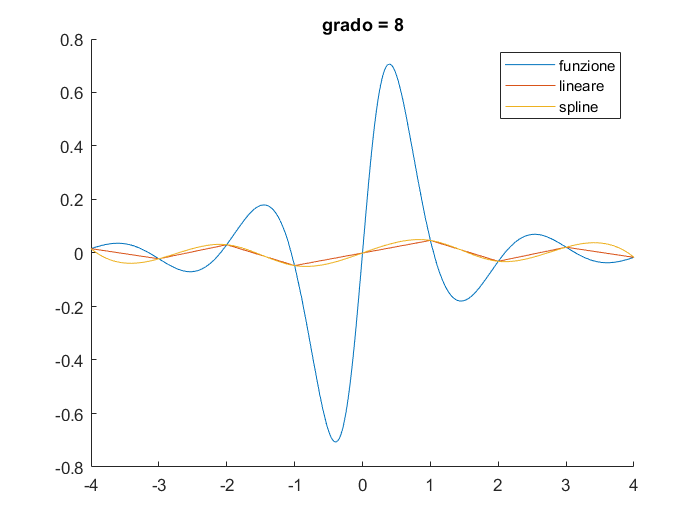

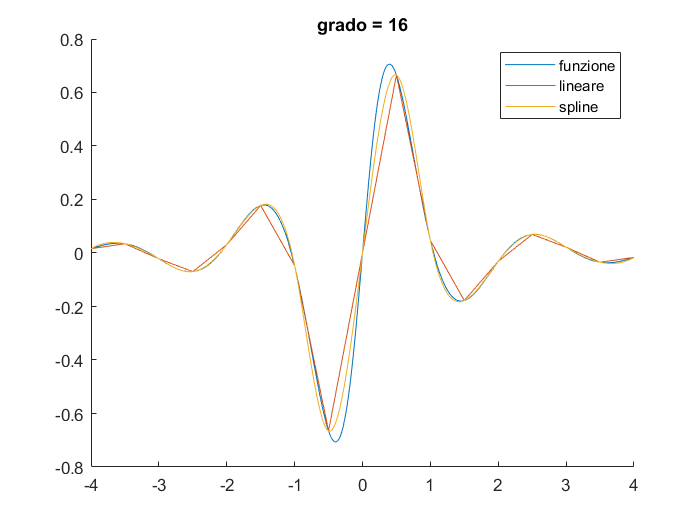

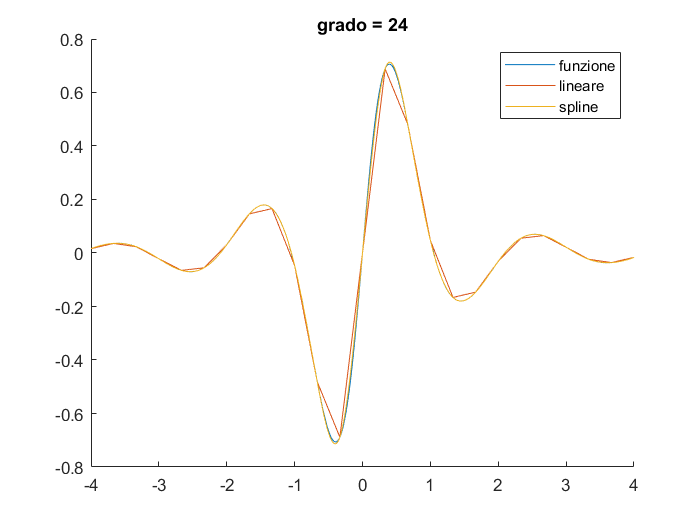

clear all
close all
f=@(x) sin(3*x)./(1+2*x.^2);
a=-4;b=4;N=256*10;
x=linspace(a,b,N);
fx=f(x);
e=[];
err=[];
for n=4:4:256
    z=linspace(a,b,n+1);
    y=f(z);
    yl=interp1(z,y,x);
    ysp=interp1(z,y,x,"spline");
    err=[err norm(fx-ysp,"inf")];
    e=[e norm(fx-yl,"inf")];
    if ismember(n,8:8:24)
        figure 
        hold on
        fplot(f,[a b])
        plot(x,yl)
        plot(x,ysp)
        legend("funzione","lineare","spline")
        title("grado = "+n)
        savefig("es1_grado"+n)
    end
end

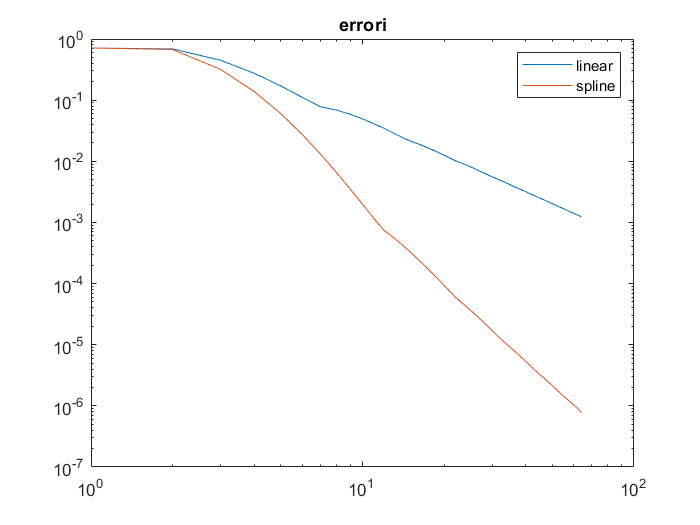

figure 
loglog(e)
hold on
loglog(err)
legend("linear","spline")
title("errori")
savefig("es1_err")

## Esercizio 2

Il file FIAT contiene i dati relativi alle quotazioni in borsa dell'azione FIAT corrispondenti a tutte le giornate della borsa di un certo anno. Si considerino i dati della prima colonna corrispondenti alla quotazione in apertura della borsa.

Rappresentare i dati con una spezzata.

Calcolare la retta di regressione lineare e riportarla nella figura insieme ai dati, a fianco riportare anche i residui. Calcolare lo scarto quadratico.

Calcolare poi i polinomi di grado 3, 5 e 7 che meglio approssimano i dati nel senso dei minimi quadrati lineari. Rappresentare ciscun polinomio insieme ai dati e riportare a fianco il grafico dei residui. Calcolare lo scarto quadratico.

In corrispondenza del calcolo dei polinomi di grado 5 e 7 si ottiene un messaggio di Warning che dice che il polinomio è mal condizionato. Per centrare e scalare i dati usare le seguenti due istruzioni

`[c,∼,mu] = polyfit(x,y,n);`

`p1=polyval(c,z,[],mu);`

essendo `x, y` i vettori contenenti i dati e `z` il vettori dei punti in cui si vuole calcolare il polinomio.

Ripetere il calcolo relativo a questo due polinomi.

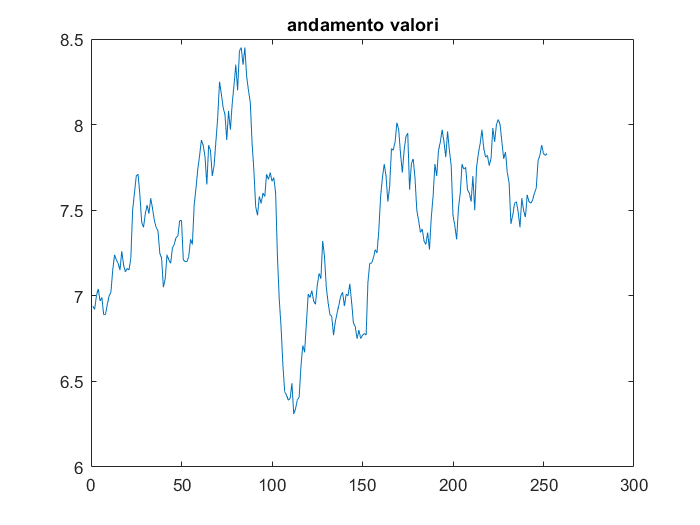

clear all
close all
FIAT
val=fiat(:,1);
day=1:length(val);
plot(val)
title("andamento valori")
savefig("es2_andamento")

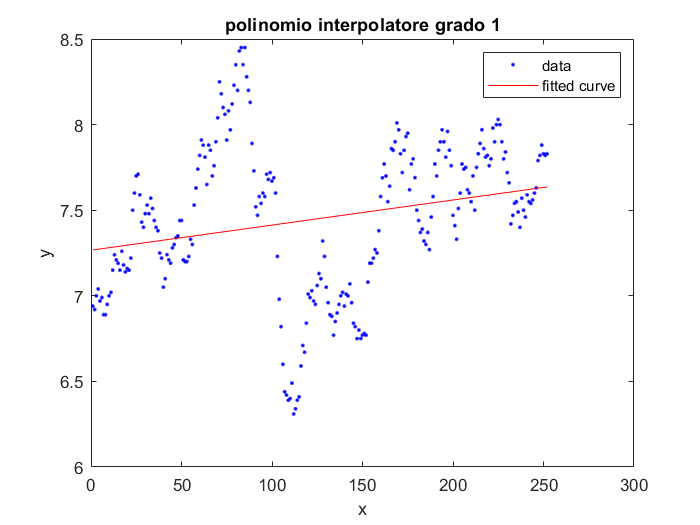

[FO, G, O] = fit(day', val, "poly1");
plot(FO,day,val)
title("polinomio interpolatore grado 1")
savefig("es2_grado1")

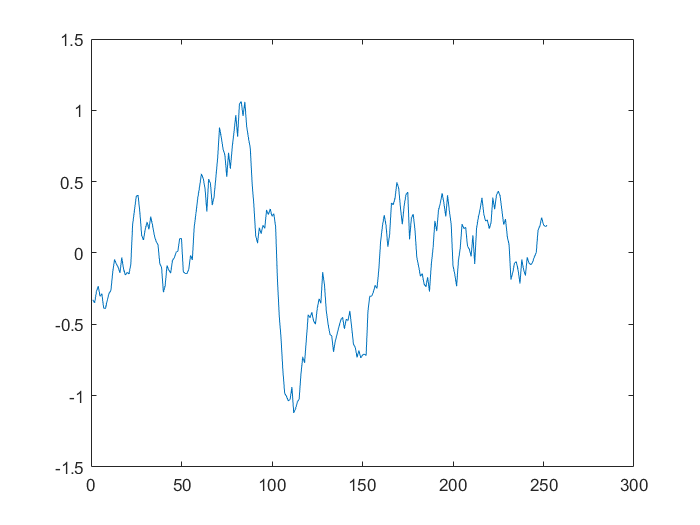

figure
plot(O.residuals)


sqm=G.sse   %scarto quadratico medio

sqm = 46.9957

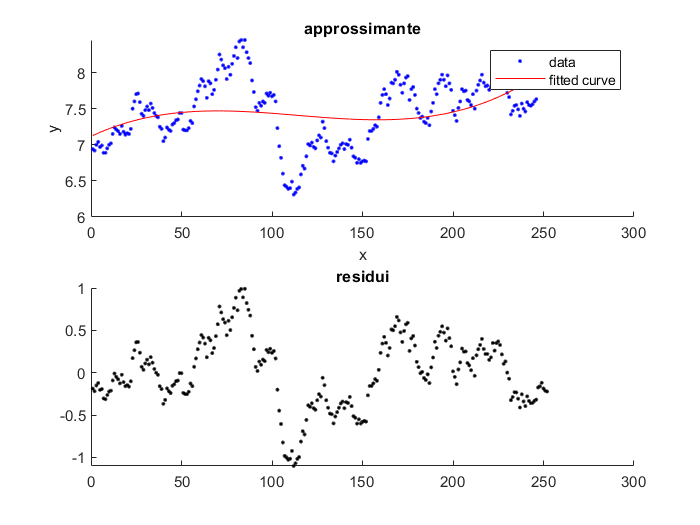

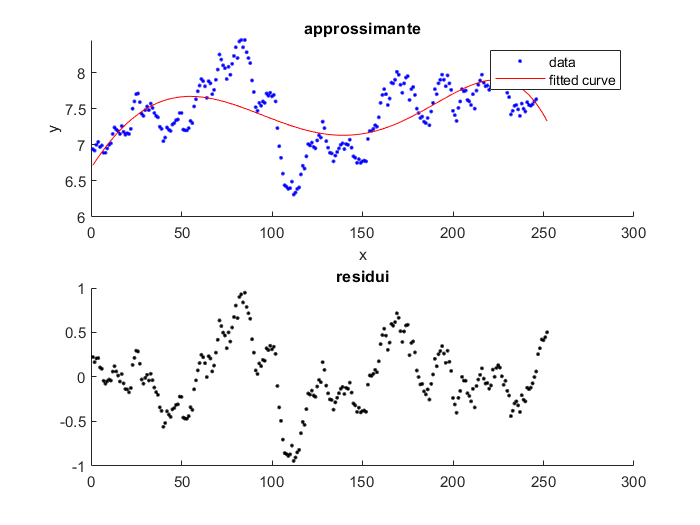

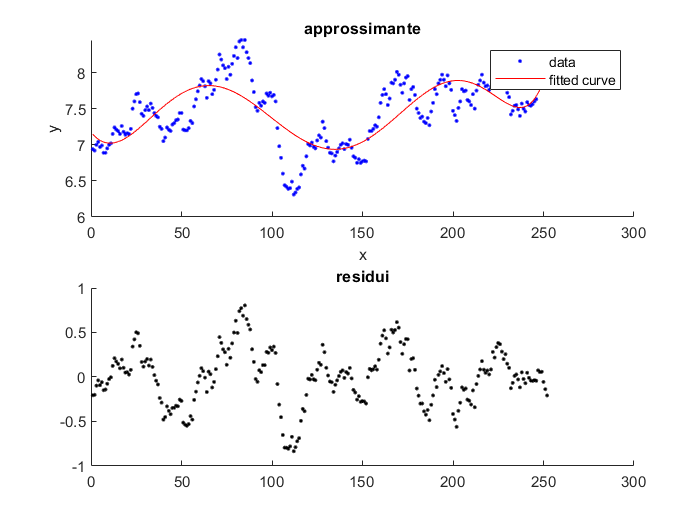

for n=3:2:7
    figure
    subplot(2,1,1)
    hold on
    [curvefit,gof,output]=fit(day',val,"poly"+n,'Normalize','on');
    title("approssimante")
    plot(curvefit,day,val)
    subplot(2,1,2)
    hold on
    
    title("residui")
    plot(output.residuals,".k")
    sqm=[sqm gof.rmse];
end